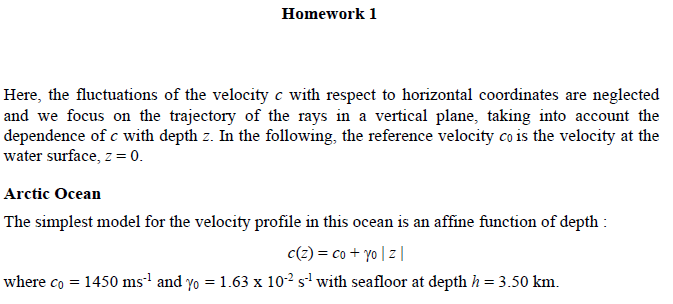

clear
clc

% Initial conditions
Co = 1450;
gamma = 1.63e-2;
h = 3500 ; % maximun depth

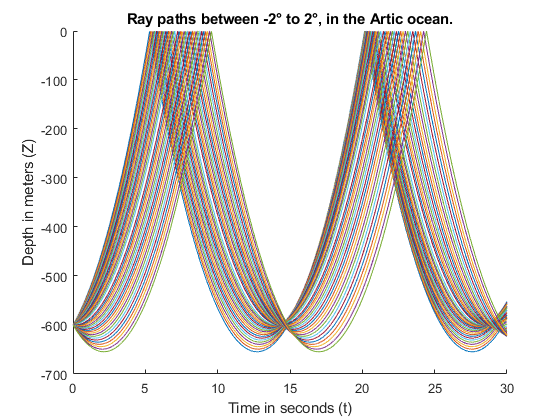

% Parameter difinition
zs = 600;
total_period = 30;
dt = 0.005; % sampling time
t = 0:dt:total_period;

% The defines the range of the angles to be analyzed
angle = -2:0.1:2;
angle = angle(angle ~= 0);

% Defines a Matrix which is going to contain the depth reached for the given
% sampling time
n_rows = length(angle);
n_columns = length(t);

ray_matrix = zeros(n_rows, n_columns);

for i = 1:length(angle)
    
    x = zeros(size(t));
    x(1) = 0;
    
    z = zeros(size(t));
    z(1) = zs;
    
    theta = zeros(size(t));
    theta(1)  = angle(i)*pi/180;
    
    c = zeros(size(t));
    c(1)=velocity(z(1),Co,gamma);
    
    ray_matrix(:,1) = z(1);
    
    for j = 2:length(t)
        
        % Calculates the distance traveled
        x(j) = x(j-1) + c(j-1) * dt * cos(theta(j-1));
        % Calculates the depth reached
        z(j) = z(j-1) + c(j-1) * dt * sin(theta(j-1));
        % Calculates the speed reached
        c(j) = velocity(z(j),Co,gamma);
        
        % Snell constant
        K = cos(theta(j-1))*c(j)/c(j-1);
        
        % Verifies the value of the Snell constant
        if K <= 1
            
            theta(j) = sign(theta(j-1))*acos(K);
            
        else
    
            z(j) = z(j-1);
            c(j) = c(j-2);
            theta(j) = -theta(j-2);
            
        end
        
        % Flips the ray in case that reach the surface or the max depth
        if (z(j) <= 0) || (z(j)>=h)
            
            z(j) = z(j-1);
            c(j) = c(j-2);
            theta(j) = -theta(j-2);
            
        end   
        
        ray_matrix(i,j) =  z(j);
        
    end
    % stores the value of the depth reached
    hold on
    plot(t,-ray_matrix(i,:))
    
end

title('Ray paths between -2° to 2°, in the Artic ocean.')
xlabel('Time in seconds (t)') 
ylabel('Depth in meters (Z)') 
hold off

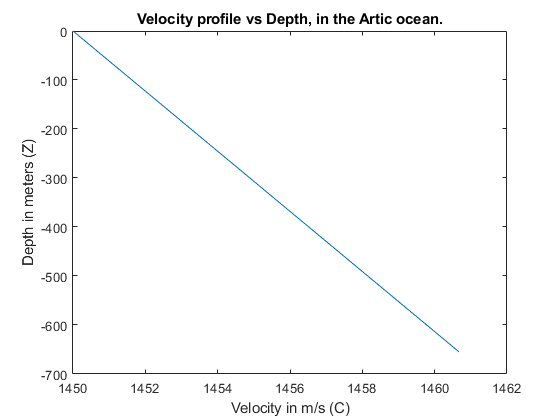

plot(c,-ray_matrix(end,:))
title('Velocity profile vs Depth, in the Artic ocean.')
xlabel('Velocity in m/s (C)') 
ylabel('Depth in meters (Z)') 

What is the maximun depth reached by this beam?

% Calculates the maximum depth storage on the ray matrix for the given
% sampling time
max_depth = max(ray_matrix(:))

max_depth = 654.5889

% Gives the angles for the maximum depth storage on the ray matrix
% for the given sampling time
[ii,jj] = find(ray_matrix == max_depth);
test = ray_matrix;
angle(ii)

ans =     -2    -2


The max maximun depth reached by the beam is $654\ldotp 5888\;$meters with $\theta =-2°$.

Knowing that:


$$ R = \frac{C(Z_s)}{cos(\theta_s)}\frac{1}{\left|\frac{dc}{dz}\right|}$$
 

and


$$ Z_c = Z_s - \frac{C(Z_s)}{\frac{dc}{dz}}$$
 

We can say that:


$$Z_{max} = Z_s - \frac{C(Z_s)}{\frac{dc}{dz}} + \frac{C(Z_s)}{cos(\theta_s)}\frac{1}{\left|\frac{dc}{dz}\right|}$$


% Call velocity function for a constant gradient
c = velocity(zs,Co,gamma);
z = zeros(1,length(angle));

% Calculates the maximum depth for an angle width

for i = 1:length(angle)
    z(i) = zs - (c/gamma) + (c/(cos(angle(i)*pi/180)*abs(gamma)));
end

% show the maximum depth storage on the z array
z_max = max(z)

z_max = 654.5890

% Finds the angles in degrees which reach the maximum depth
% for the initial conditions with a constant gradient
angle_max = find(z == z_max);
angle(angle_max)

ans =     -2     2


% Simbolic parameter definition

syms z 
syms z C_0 gamma_0
f = 1/(C_0+(gamma_0*abs(z)))

$$f = \frac{1}{C_{0}+\gamma_{0}\,\left|z\right|}$$

f = 1/(1450+(0.0163*abs(z)));
% time to reach seafloor
t = vpaintegral(f,z,[0 3500])

$$t = 2.36752$$

% time round trip
total_time = t*2

$$total\_time = 4.7350357253758147968447644871048$$


% Parameter difinition
zs = 0;
total_period = 30;
dt = 0.005;
t = 0:dt:total_period;
angle = 90;


for i = 1:length(angle)
    
    x = zeros(size(t));
    x(1) = 0;
    
    z = zeros(size(t));
    z(1) = zs;
    
    theta = zeros(size(t));
    theta(1)  = angle(i)*pi/180;
    
    c = zeros(size(t));
    c(1)=velocity(z(1),Co,gamma);
    
    ray_matrix(:,1) = z(1);
    
    for j = 2:length(t)
        
        % Calculates the distance traveled
        x(j) = x(j-1) + c(j-1) * dt * cos(theta(j-1));
        % Calculates the depth reached
        z(j) = z(j-1) + c(j-1) * dt * sin(theta(j-1));
        % Calculates the speed reached
        c(j) = velocity(z(j),Co,gamma);
        
        % Snail constant
        K = cos(theta(j-1))*c(j)/c(j-1);
        
        % Verifies the value of the snell constant
        if K <= 1
            
            theta(j) = sign(theta(j-1))*acos(K);
            
        else
    
            z(j) = z(j-1);
            c(j) = c(j-2);
            theta(j) = -theta(j-2);
            
        end
        
        % Flips the ray in case that reach the max depth
        
        if z(j)>=h
            
            z(j) = z(j-1);
            c(j) = c(j-2);
            theta(j) = -theta(j-2);
            
        elseif z(j) <= 0
            
            % Flips the ray in case that reach the surface and stop the calculation when reach the round trip
            z(j) = z(j-1);
            c(j) = c(j-2);
            theta(j) = -theta(j-2);
            
            % Change the vector' size to match the time of the round trip
            sprintf('The time for a round trip under a vertical from the surface is %f seconds',t(j))
            x = x(1:j);
            c = c(1:j);
            z = z(1:j);
            t = t(1:j);
            break
            
        end   

        
    end
    

   
    
end

ans = 'The time for a round trip under a vertical from the surface is 4.735000 seconds'

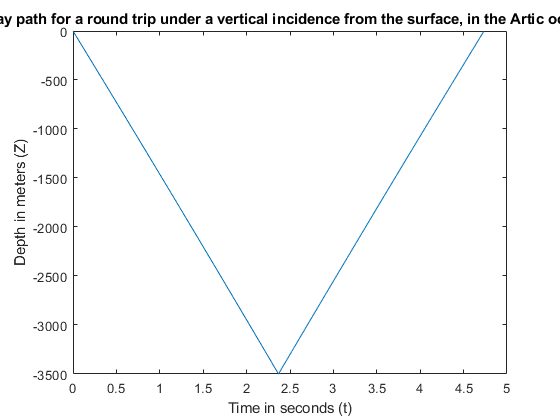

plot(t,-z)
title('Ray path for a round trip under a vertical incidence from the surface, in the Artic ocean.')
xlabel('Time in seconds (t)') 
ylabel('Depth in meters (Z)') 
hold off

function c = velocity(z, Co, gamma)
    % Calculates the Velocity for a constant gradiente for a given depth 
    c = Co + gamma*abs(z); 
end